# AccelerationInFreeFall

*D. Carlsmith*

Examination of iPhone 7 audio recording of 60-cycle triggered spark generator for acceleration in free fall experiment. 

An line-frequency-triggered spark generator can be used in a free fall experiment in which a falling mass drags a paper-tape through the periodic spark, leaving visible marks in the tape at time intervals of 1/60 s. The displacement of the mass over time is deduced from measurements of the locations of the marks in the tape.

The power line frequency stabilty is subject to regulation to support legacy clocks which rely upon the frequency. The standard error on the 60-cycle frequency in the US is [expected to be](http://www.nerc.com/pa/RAPA/ra/Pages/default.aspx) 0.025 Hz in random 1-minute intervals.  The deviations from the mean in different districts are as much as 1/5th of the standard error and drift is subject to periodic correction.

Does the spark generator acoustic signal indicate a similar error, or are there additional sources of jitter in the time difference between sparks which could impact the free fall measurements? (The variation in the position of the spark within the generator gap is not considered here.)

This question may be addressed by examining an audio recording of the spark generator in operation. This MATLAB Live script script examines such recordings made with a smart phone.

## Read in and examine audio files. 

Read a short sample (when turning the generator on and off) and plot the signal versus time. The function [audioread](https://www.mathworks.com/help/matlab/ref/audioread.html) recognizes a variety of audio file types (see its documentation) from the filename. You may need an external application to convert an unsupported file type to a supported file type. Digital audio standard files assume the acoustic pressure (or velocity) is sampled at regular time intervals, typically in excess of 40 kHz to cover the 20 kHz nominal range of human hearing, but as low at 8KhZ for low quality audio with reduced file size. We catch a vector `ys` of audio signals and the sampling frequency `fs`.

[ys,fs]=audioread('audio\short.m4a');% ys is the signal, fs the sample rate.

 We assume mono audio. For stereo audio, ys will be a 2 column array of "left" and "right" signals so, just in case, let's use just the first column.

ys=ys(:,1);

Compute a vector of times using the sample rate and plot the data.

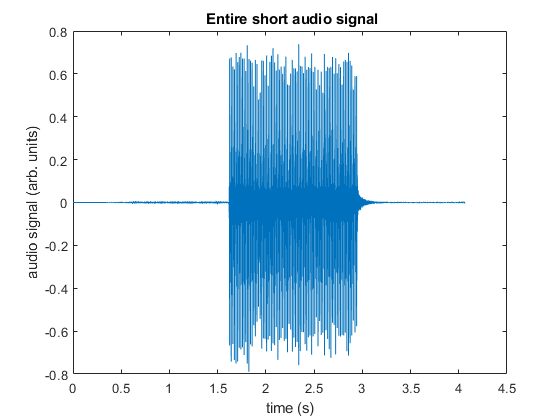

t=[1:length(ys)]/fs -1/fs;% times in s starting at 0
plot(t,ys); 
xlabel('time (s)');ylabel('audio signal (arb. units)')
title(' Entire short audio signal')

Notice that an audio signal is typically a double with values ranging from minus one to plus one. Typically the [bit depth](https://en.wikipedia.org/wiki/Audio_bit_depth) that ultimately limts the precision of the audio samples is 16-bits.

**Try this**: Zoom in and pan to examine the data in detail. There appears a 60-cycle hum when the generator is off, then pulses, each followed by room reverberation signals merging with each other, during the spark-generator-on period.

Next, examine a longer sample of just sparks.

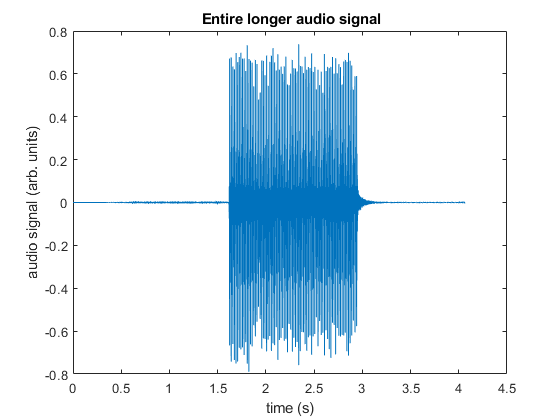

[y,fs]=audioread('audio\short.m4a');
y=y(:,1);
t=[1:length(y)]/fs -1/fs;% times in s starting at 0
plot(t,y); 
xlabel('time (s)');ylabel('audio signal (arb. units)')
title(' Entire longer audio signal')

The recorded spark peak amplitudes appear to decrease with time. That decrease could reflect a change in the generator behavior from  electrode surface degradation,  a microphone response effect, the phone adjusting its audio sensitivity to not saturate its audio output, or it might result from acoustic reflections from an observer who was not stationary. (The increase in amplitude near the end suggests the last hypothesis.)

Create an [audioplayer](https://www.mathworks.com/help/matlab/ref/audioplayer.html) object to play the acoustic data.

playerObj = audioplayer(y,fs);

Define by inspection start and ends times (in seconds) of valid range.

tstart=1.65;tend=3; % for the short sample
%tstart = 1/fs;tend=18; % for the long sample

Compute corresponding sound data array indices and [play](https://www.mathworks.com/help/matlab/ref/audioplayer.play.html) the audio over the default system audio output device, likely your laptop speakers or a connected headset if your are running this script on a laptop.

starttime = playerObj.SampleRate * tstart; % start play at tstart
endtime = playerObj.SampleRate * tend; % end play at tend
% play(playerObj,[starttime,endtime]);

Define a valid range and a snippet range of data indices to zoom in on about 20 cycles (for a 60-cycle signal), and plot the snippet signal.

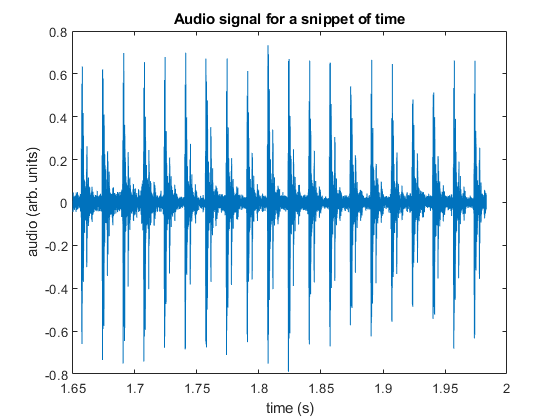

range0=t>tstart&t<tend;% define valid range (s)
range1=t>tstart&t<tstart+20*(1/60);% define a snippet (s)
plot(t(range1),y(range1));
xlabel('time (s)');ylabel('audio (arb. units)');
title('Audio signal for a snippet of time')

Use [findpeaks](https://www.mathworks.com/help/signal/ref/findpeaks.html) to identify the sparks, using the snippet as a test. The algorithm searches for the highest peak within constraints designed to separate sparks, not the first peak in the spark signal, and plots the data indicating the peaks with triangles by default. 

**Try this**: Open the figure in a separate window and zoom to explore how well it is working. Play with peak finding parameters to optimize. Change from range1 to range0 to peak-find over the whole valid range. Change the Threshold, MinPeakHeight, and MinPeakDistance to match your data.

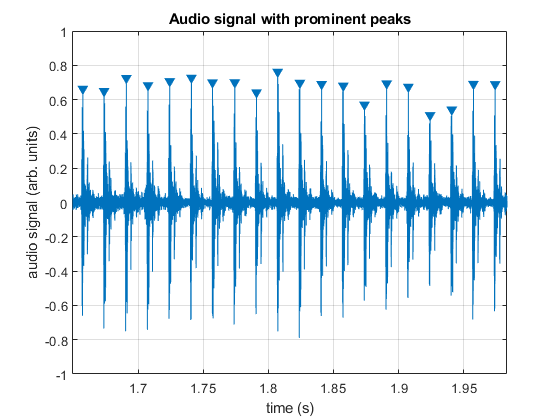

findpeaks(y(range1),t(range1),'Threshold',.1,...
    'MinPeakHeight',.4, 'MinPeakDistance',.75/60)
xlabel('time (s)');ylabel('audio signal (arb. units)')
title('Audio signal with prominent peaks')

Apply the same selection to find peaks over the whole sample using range0. `findpeaks` returns locations (times where found peaks are located) when requested.

[pks,locs]=findpeaks(y(range1),t(range1),'Threshold',.1,...
    'MinPeakHeight',.4, 'MinPeakDistance',.75/60);

Get all the time differences `difflocs` between successive peaks using [diff](https://www.mathworks.com/help/matlab/ref/diff.html) to calculates the differences between adjacent elements in the vector `locs`  returned by f`indpeaks`, and histogram them in units of milliseconds.

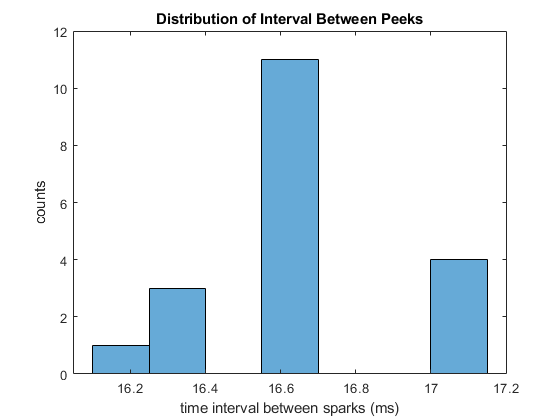

difflocs=diff(locs);
histogram(difflocs*1000, 7)
xlabel('time interval between sparks (ms)');
ylabel('counts');
title("Distribution of Interval Between Peeks")

Notice there is are a few outliers near 33 ms probably resulting from findpeaks missing a spark or two. Select a range around the peak in time differences to compute a mean and standard deviation of the time differences for the region near the peak.

frac=.1; %half-width of fractional range
difflocsselect= difflocs(difflocs<(1+frac)/60&difflocs>(1-frac)/60);
meanCycle = mean(difflocsselect) % mean distance between peaks (s)

Array indices must be positive integers or logical values.

stdCycle = std(difflocsselect)% std of distance between peaks (s)

Convert mean and standard deviation of time intervals $T$ in seconds between sparks to spark frequency $f$and frequency standard deviation in Hz using a simple propagation of errors formula  $\sigma_f/f = \sigma_T/T$.

(Note: The time differences are correlated so interpret with care.)

meanFreq=1/meanCycle % Hz
stdFreq=meanFreq*stdCycle/meanCycle % Hz
nPeaks=length(difflocsselect) 

The number of differences used naively suggests an error on the mean frequency of about 0.9 Hz/sqrt(1000)=0.03 Hz. This result is consistent with the expected 0.025 Hz but statistics (and systematics) limited.

Let's take a closer look the acoustic signal of a single spark. It looks like it results from repeated N-waves (each resulting from a shock in the air) or  from a single shock wave  bouncing around. The peak heights are affected by 60-cycle (hum) noise and interference.

range2=t>3.504&t<3.511;
plot(t(range2),y(range2)); 
xlabel('time (s)');ylabel('audio (arb. units)')

Aside, power use variations leave identifiable signatures in 60-cycle hum. See  [The hum that helps to fight crime](https://www.bbc.co.uk/news/science-environment-20629671 ).